Clearing the workspace.

clc; clear all; close all;

## **1) Dataset**

a) To import the dataset with .dat extension to matlab, use the function readtable(), which will creat a table containing the data, and this table needs to be converted to array to be processed, but these two steps are relevant only before saving the dataset in .mat extension.

now load the dataset with .mat extension and split it into two variables, input and output

% dataset = readtable("evaporator.dat");
% dataset = table2array(dataset);
load("evaporator.mat");
input = dataset(:,1:3);
output = dataset(:,4:6);

b) to create an identification data object, use the MATLAB function iddata()

Ts = 1;
ident_data = iddata(output, input, Ts);

c) to rename the dataset outputs and inputs, need to cast the types of the string names to cell since this is the form the table columns in.

ident_data.InputName(1) = cellstr("Flow of feed product");
ident_data.InputName(2) = cellstr("Flow of vapor");
ident_data.InputName(3) = cellstr("Flow of cooling water");
ident_data.OutputName(1) = cellstr("Dry matter content of the product");
ident_data.OutputName(2) = cellstr("Flow of the outcoming product");
ident_data.OutputName(3) = cellstr("Temperature of the outcoming product");
ident_data.TimeUnit = 'sec';

d) To plot the dataset which at this point an identification object use the function idplot()

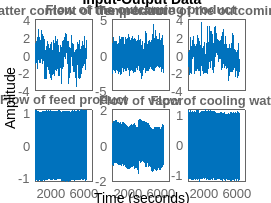

idplot(ident_data);

% save('evaporator.mat');

e) to split the dataset into identification and validation, first find the size of the dataset, the number of rows specifically and divide it by two then slice the dataset into two new variables.

size(ident_data);

Data set with 3 output(s) and 3 input(s).
The number of data points is 6305.


id_data = ident_data(1:3152, :);
val_data = ident_data(3153:6304,:);

## **2) Impulse response**

a) to estiamte an impulse response model use the function impulseest()

mod = impulseest(id_data);

b) plotting the step response for the impulse model is done by 

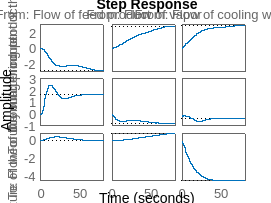

step(mod)

c) from the nine graphs in the previous question could notice the following:

- the first input which is the flow of feed product when it increases results in a decrease in the dry matter content of the product, and the response of the system at the second output which is the flow of the outgoing product with the change of the flow of the feed product is underdamped since it shows an overshoot,.while the temperature of the outcoming product only slightly change with the change of the flow of the feed product.

- for the plots of the second input which is the flow of vapor, shows that when the flow of vapor increases the dry matter content of the product increase too, and that is the same but in a smaller extent for the tamperature of the outgoing product, while the proportionality of the flow of vapor with the flow of the outcoming product is reversed, i.e. when the input increase the output decrease.

- for the flow of cooling water which is the third input and shown in the third column of the graph, the plot with the dry matter content of the product shows that increasing the flow of the cooling water will increase the dry matter content of the product, and the flow of the outcoming product almost does not get affected with the flow of cooling water, but for the temperature of the outcoming product which is the third output, it decrease sharply with the increase of the flow of cooling water, and this is expected since the cooling water will cool down the product temperature.

the plots of the inputs against the outputs shows results in reasonable ranges and expected behaviours from the system, so will proceed to the next question.

## **3) Feedthrough**

a) when considering the system and the relations between the inputs and outputs could notice that the output that is controlled directly by the input signal, is most likely to be the product temperature and it is controlled with the cooling water flow input. and that would give the suspicion that the feedthrough is non zero.

b) using the ssest to find the best order for the system

sys_ord = ssest(id_data, 1:10);
syswf_ord = ssest(id_data, 1:10,'Feedthrough', 1);

in both cases i.e. with/without feedthrough the best order for the system is 8, so now will compare between the data fit for the order 8 system to check the difference between having a feedthrough or not

sys = ssest(id_data, 8);
syswf = ssest(id_data, 8,'Feedthrough', 1);

and that shows the system estimated in the second case has a better fit to the data than the estimation in the first case, supports the idea that the system has a feedthrough.

knowing that the difference between the two functions is that SSEST estimates a continous-time state space representation and N4SID estimates discrete-time state space representation then for this question the estimation using SSEST is the solution and for the next question will use N4SID.

## **4) MPC design**

 a) to estimate a discrete-time state-space representation for the system need to use the N4SID function, and to test for the best model orders use the same function and as follows:

system = n4sid(id_data, 1:10, 'Feedthrough', 1);

in range of 1 to 10 order searching for the best one, the result is 8, so for that will consider the model with orers 7, 8, 9 for further testing.

b) to find the state space models for the sysems orders chosen, run the following:

system_order_7 = n4sid(id_data,7, 'Feedthrough', 1);
system_order_8 = n4sid(id_data, 8, 'Feedthrough', 1)

system_order_8 =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1     0.9712  -0.004091   -0.01669  -0.002537    0.04678   -0.02214    -0.0446  -0.008783
   x2   0.000756      0.951    0.07978     0.1042  -0.004426   -0.07277  -0.006859    0.03284
   x3     0.0114    -0.1603     0.9414    0.08292  -0.004865  -0.009818    0.01198    -0.0256
   x4    0.01692    -0.1478    -0.1883     0.8847    0.02944     0.2388   -0.03929   -0.06106
   x5   -0.08023    0.02684    0.03702      0.086     0.8805    0.05191     0.3029    0.03735
   x6    0.08277    0.07373     0.1036    0.05831    0.05855     0.5417    -0.1811     0.4885
   x7    0.07663  -0.009031   -0.01203   -0.05234    0.07455   -0.06153     0.8038     -0.162
   x8   -0.03085  0.0002253  0.0006827  -0.002253    -0.1445     0.2666     0.2867     0.4056
 
  B 

system_order_9 = n4sid(id_data, 9, 'Feedthrough', 1)

system_order_9 =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8         x9
   x1     0.9703   0.002875    0.01618   0.001996     0.0353    0.01929    0.03908    0.02211    0.02369
   x2  0.0008834     0.9515    0.08219    0.09968    0.01053   -0.07236  -0.003828    0.03108   0.002665
   x3   -0.01277    -0.1626     0.9413    0.07599   0.005147   -0.02055   0.008385   -0.02315     0.0212
   x4   -0.02188    -0.1395    -0.1739     0.9024   -0.02859     0.1947   -0.02097   -0.05916    -0.1019
   x5   -0.05696   -0.02733   -0.03915   -0.07742     0.9351      0.017    -0.2161    -0.1129    -0.1197
   x6   -0.08268    0.08961     0.1237    0.06744    0.01077     0.5828    -0.1219     0.2841     0.4887
   x7   -0.08756  -0.004909   -0.01494   -0.06789   -0.04119    -0.0659     0.7875    -0.1181    -0.2203
   x8    0.0

c) to validate the models chosen using the validation data, run the following:

step_count = 5

step_count = 5

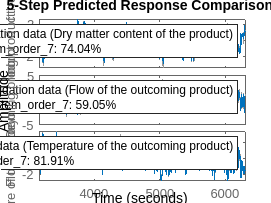

compare(val_data, system_order_7, step_count)   % compare the model to validation data

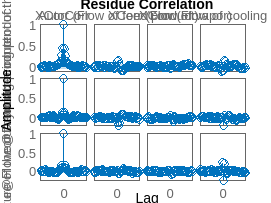

resid(val_data, system_order_7)                 % calculate the residuals and correlation

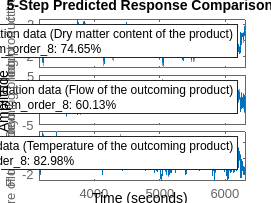

compare(val_data, system_order_8, step_count)

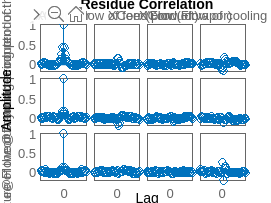

resid(val_data, system_order_8)

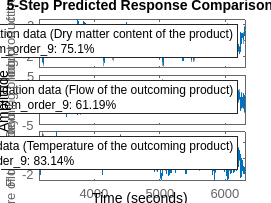

compare(val_data, system_order_9, step_count)

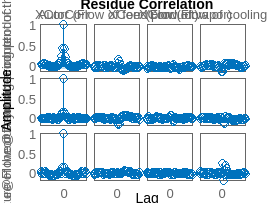

resid(val_data, system_order_9)

d) from the models validated above it is best to implement the model of order 8 since on the validation process shows less fit to the data on the first two outputs but significantly less on the third output, but when observing the residuals plot will notice that the on the autocorrelation plots the data stays in the confidence region while on the bigger order model, the points are out of the confidence region.

still the results shows a bit of disturbance effects are being captured so adding a noise model might improve the result

system_order_8_dist = n4sid(id_data, 8, 'Feedthrough', 1, 'DisturbanceModel', 'estimate')

system_order_8_dist =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1     0.9712  -0.004091   -0.01669  -0.002537    0.04678   -0.02214    -0.0446  -0.008783
   x2   0.000756      0.951    0.07978     0.1042  -0.004426   -0.07277  -0.006859    0.03284
   x3     0.0114    -0.1603     0.9414    0.08292  -0.004865  -0.009818    0.01198    -0.0256
   x4    0.01692    -0.1478    -0.1883     0.8847    0.02944     0.2388   -0.03929   -0.06106
   x5   -0.08023    0.02684    0.03702      0.086     0.8805    0.05191     0.3029    0.03735
   x6    0.08277    0.07373     0.1036    0.05831    0.05855     0.5417    -0.1811     0.4885
   x7    0.07663  -0.009031   -0.01203   -0.05234    0.07455   -0.06153     0.8038     -0.162
   x8   -0.03085  0.0002253  0.0006827  -0.002253    -0.1445     0.2666     0.2867     0.4056
 

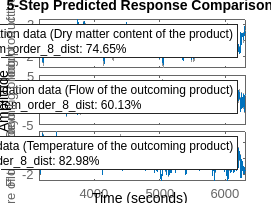

compare(val_data, system_order_8_dist, step_count)

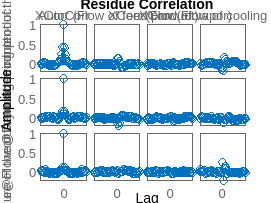

resid(val_data, system_order_8_dist)

but the model does not show an improved fitting to the data after adding the disturbance model.